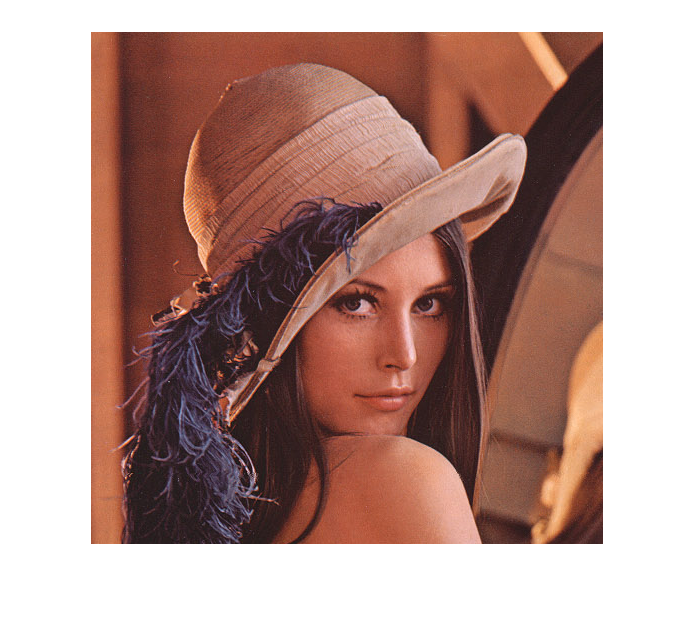

clc;
clear all;
close all;
im  = imread('Images\Lena_Color.png');
figure;
imshow(im);

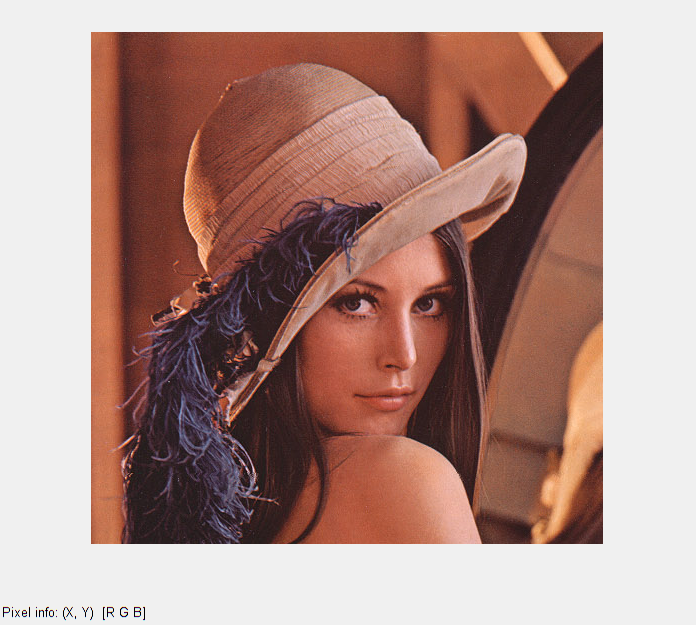

impixelinfo


pix = im(136, 191, :);
pix_sq = squeeze(pix);
pix2 = [0;0;255];
im(136, 191, :) = pix2;

Change the pixel color

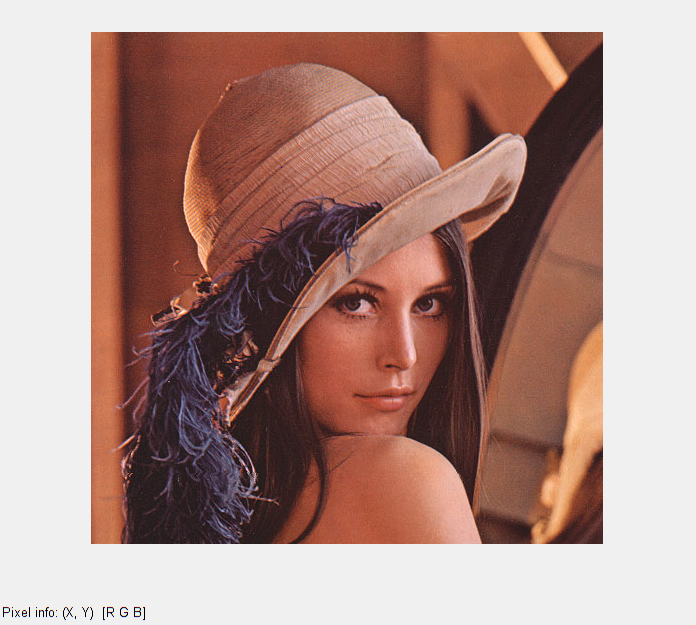

figure;
imshow(im);
impixelinfo

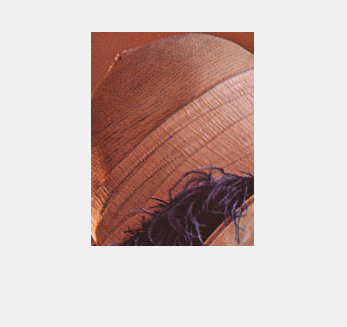

row1 = 31;
col1 = 112;
row2  = 244;
col2 = 274;
im2= im(row1:row2, col1:col2,:);
imshow(im2);

Extract image portion from the main image

Save the extracted image

imwrite(im2, 'lena_subset.jpg');

Extract the red, green and blue channels from the image

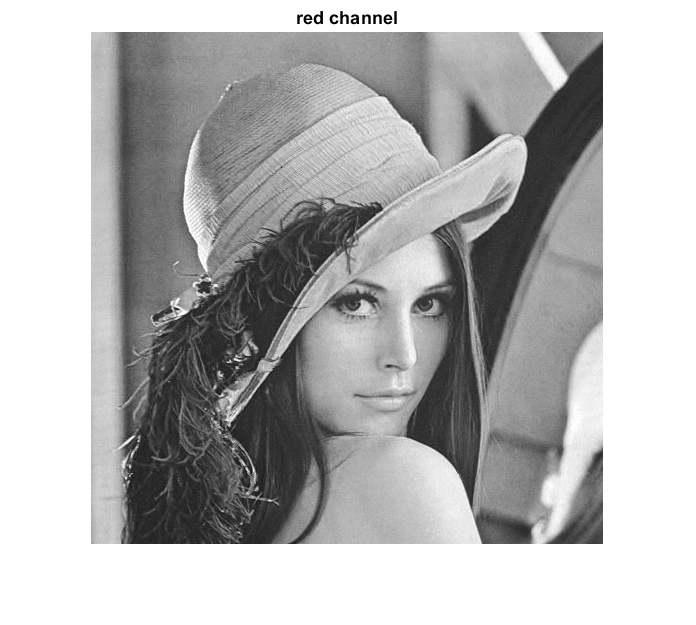

figure;
imshow(im(:,:,1));
title('red channel')

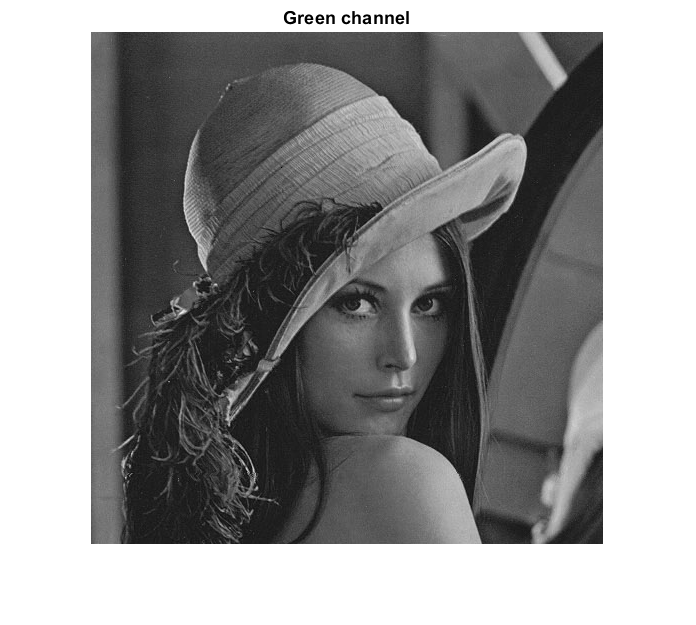



figure;
imshow(im(:, :, 2));
title('Green channel');

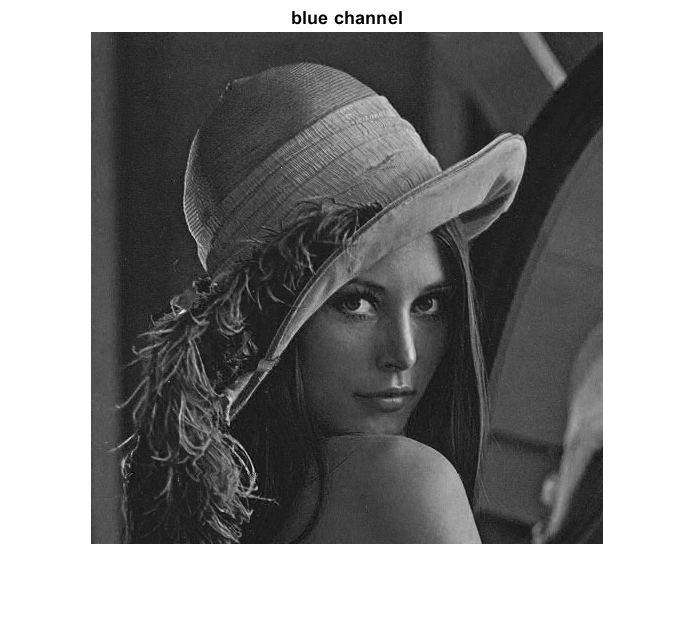



figure;
imshow(im(:, :, 3));
title('blue channel');

Image resize

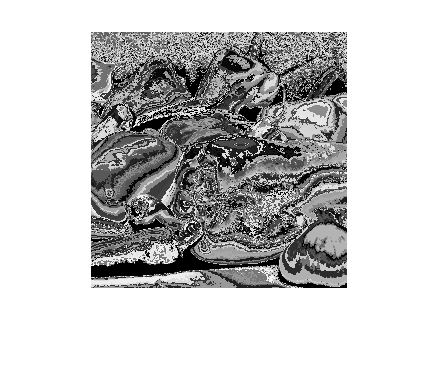

im2 = imread('Images\pepper.png');
figure;
imshow(im2);

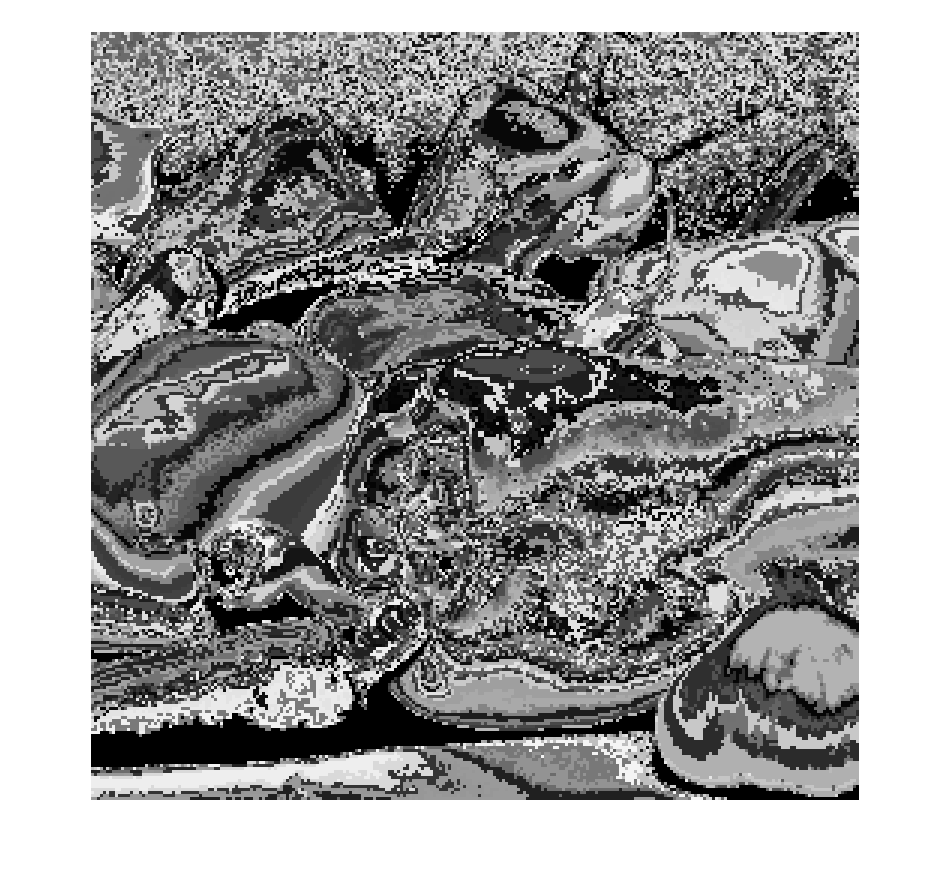

im2 = imresize(im2, 3, 'nearest');
figure;
imshow(im2);